% Prep the workspace
clear vars; close all; clc;

% The goal is to create something that realistically looks like localization data in 2 channels
% As such what we'll do is create an initial distribution of point
% Transform them on another channel
% Build and interpolation to mimic the transform
% Apply the interpolation to see how it performs as a corrective measure

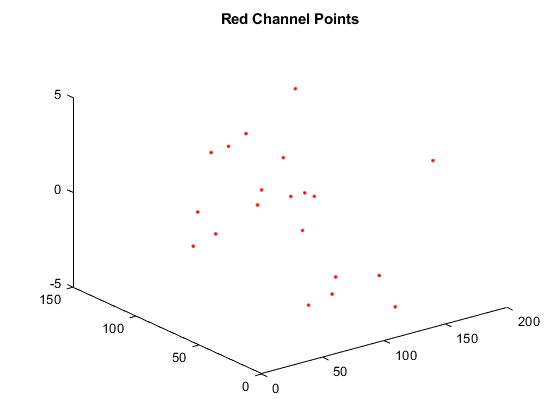

% Create an initial distribution of point for 'red' channel
number_of_points = 20;
channel_width = 180;
channel_height = 150; % Height and width are in pixels
channel_depth = 1/0.122; % Z-position bound

% Create distribution of points scatter around the channel
x_positions = rand(number_of_points,1)*channel_width;
y_positions = rand(number_of_points,1)*channel_height;
z_positions = (rand(number_of_points,1)-0.5)*channel_depth;
% display points
plot3(x_positions,y_positions,z_positions,'.r')
title('Red Channel Points')

% Transform points onto another channel

% Create a vector for transformation, centering the X and Y around 0
red_xyz_vector = [x_positions - channel_width/2, y_positions - channel_height/2, z_positions];

% Build Spatial Transformations consisting of magnifcation and rotation
magnification_matrix = [ 1.01, 0.01, 0.06;
                         0.05, 1, .05;
                         0, 0, 0.9]

magnification_matrix =     1.0100    0.0100    0.0600
    0.0500    1.0000    0.0500
         0         0    0.9000


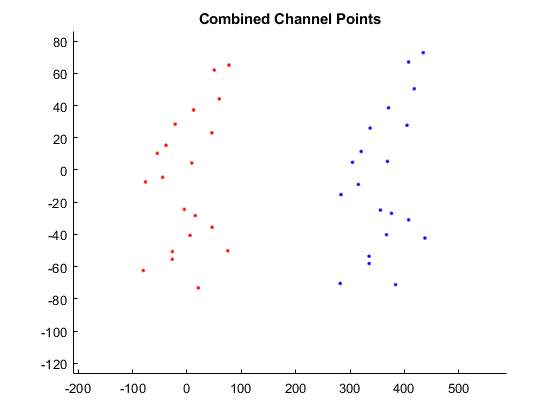

% magnification_matrix = randn(3) + 1
% rotation_angle = deg2rad(rand(1)*180);
rotation_angle = deg2rad(3);
[X, Y, Z] = rot_mat(rotation_angle);
orange_xyz_vector = (Z*magnification_matrix*red_xyz_vector.').';
orange_xyz_vector(:,1) = orange_xyz_vector(:,1) + 2*channel_width;
orange_xyz_vector(:,2) = orange_xyz_vector(:,2);

figure
plot3(red_xyz_vector(:,1),red_xyz_vector(:,2),red_xyz_vector(:,3),'.r')
hold on
plot3(orange_xyz_vector(:,1),orange_xyz_vector(:,2),orange_xyz_vector(:,3),'.b')
hold off
title('Combined Channel Points')

% view([0,90])

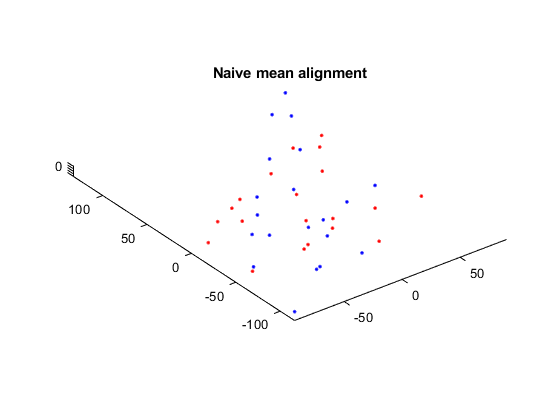

% Perform "naive" transformation

% Center all points by mean positions
for i = 1:3
    naive_red_xyz_vector(:,i) = red_xyz_vector(:,i) - mean(red_xyz_vector(:,i));
    naive_orange_xyz_vector(:,i) = orange_xyz_vector(:,i) - mean(orange_xyz_vector(:,i));
end
figure
plot3(naive_red_xyz_vector(:,1),naive_red_xyz_vector(:,2),naive_red_xyz_vector(:,3),'.r')
hold on
plot3(naive_orange_xyz_vector(:,1),naive_orange_xyz_vector(:,2),naive_orange_xyz_vector(:,3),'.b')
hold off
axis equal
title('Naive mean alignment')

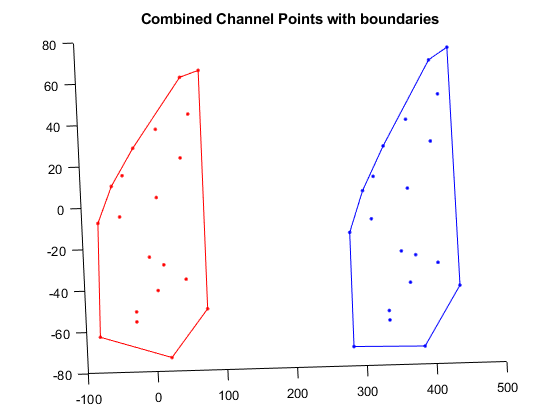

% Perform No Z Channel Calibration Method

% Get Boundary points
boundary_red = boundary(red_xyz_vector(:,1),red_xyz_vector(:,2), 0);
boundary_orange = boundary(orange_xyz_vector(:,1),orange_xyz_vector(:,2),0);
figure % Plot points
plot3(red_xyz_vector(:,1),red_xyz_vector(:,2),red_xyz_vector(:,3),'.r')
hold on
plot3(orange_xyz_vector(:,1),orange_xyz_vector(:,2),orange_xyz_vector(:,3),'.b')
title('Combined Channel Points with boundaries')
% view([0,90])
% Plot boundary
plot3(red_xyz_vector(boundary_red,1),red_xyz_vector(boundary_red,2),red_xyz_vector(boundary_red,3),'r')
plot3(orange_xyz_vector(boundary_orange,1),orange_xyz_vector(boundary_orange,2),orange_xyz_vector(boundary_orange,3),'b')
hold off

% Grab number of boundary points sufficient to specify interpolation
boundary_index = [1 2 3 4 5 6];
% Build Interpolation calculation matrix using feature vector
MX = xy_feature(orange_xyz_vector(boundary_orange(boundary_index),1),orange_xyz_vector(boundary_orange(boundary_index),2));

MY = MX;
% Add the 'red result' in the final column
MX = [MX, red_xyz_vector(boundary_red(boundary_index),1)];
MY= [MY, red_xyz_vector(boundary_red(boundary_index),2)];
MX = rref(MX); % Row reduction to solve the system of equations
MY = rref(MY);

% After Row Reduction we should have our components in the final vector
orange_2_red_x = MX(:,end);
orange_2_red_y = MY(:,end);

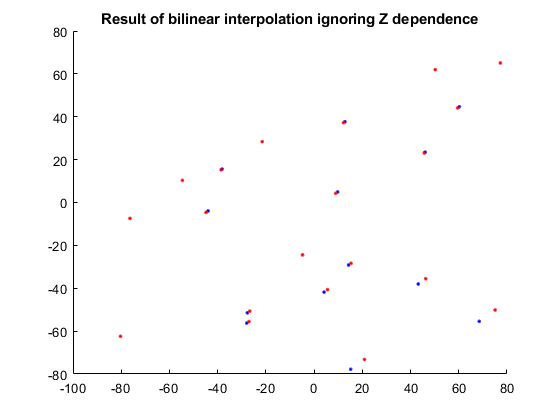

% Perform "Bilinear" interpolation transformation
vector_2_transform = xy_feature(orange_xyz_vector(:,1),orange_xyz_vector(:,2));
orange_bilinear_x = orange_2_red_x.'*vector_2_transform.';
orange_bilinear_y = orange_2_red_y.'*vector_2_transform.';
orange_bilinear_z = orange_xyz_vector(:,3);

figure % Plot points
plot3(red_xyz_vector(:,1),red_xyz_vector(:,2),red_xyz_vector(:,3),'.r')
hold on
plot3(orange_bilinear_x, orange_bilinear_y, orange_bilinear_z, '.b')
hold off
title('Result of bilinear interpolation ignoring Z dependence')

% view([0,90])

At this point it becomes clear that the bilinear is not always performing well enough, we could move to a bicubic for increased performance, but in the end we're missing Z information

% Encode tricubic transformation
% Trilinear requries 10 terms, we need 10 points
bunch_o_points = randperm(numel(orange_xyz_vector(:,1)),4);
% Build Interpolation calculation matrix using feature vector
MX = xyz_feature(orange_xyz_vector(bunch_o_points,1),orange_xyz_vector(bunch_o_points,2),orange_xyz_vector(bunch_o_points,3));
MY = MX;
MZ = MY;
% Add the 'red result' in the final column
MX = [MX, red_xyz_vector(bunch_o_points,1)];
MY = [MY, red_xyz_vector(bunch_o_points,2)];
MZ = [MZ, red_xyz_vector(bunch_o_points,3)];
MX = rref(MX) % Row reduction to solve the system of equations

MX =     1.0000         0         0         0    1.2259
         0    1.0000         0         0   -0.0218
         0         0    1.0000         0   -0.2709
         0         0         0    1.0000 -441.3348


MY = rref(MY)

MY =     1.0000         0         0         0   -0.5641
         0    1.0000         0         0   -0.0534
         0         0    1.0000         0    0.9244
         0         0         0    1.0000  203.0588


MZ = rref(MZ)

MZ =     1.0000         0         0         0    0.0000
         0    1.0000         0         0    1.1111
         0         0    1.0000         0    0.0000
         0         0         0    1.0000   -0.0000


% After Row Reduction we should have our components in the final vector
orange_2_red_x = MX(:,end);
orange_2_red_y = MY(:,end);
orange_2_red_z = MZ(:,end);

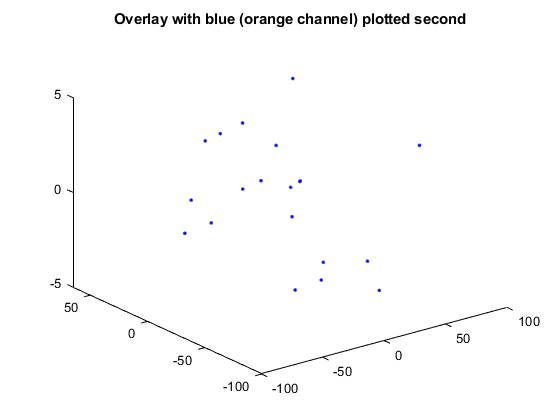

% Perform "Trilinear" interpolation transformation
vector_2_transform = xyz_feature(orange_xyz_vector(:,1),orange_xyz_vector(:,2),orange_xyz_vector(:,3));
orange_bilinear_x = orange_2_red_x.'*vector_2_transform.';
orange_bilinear_y = orange_2_red_y.'*vector_2_transform.';
orange_bilinear_z = orange_2_red_z.'*vector_2_transform.';

figure % Plot points
plot3(red_xyz_vector(:,1),red_xyz_vector(:,2),red_xyz_vector(:,3),'.r')
hold on
plot3(orange_bilinear_x, orange_bilinear_y, orange_bilinear_z, '.b')
hold off
title('Overlay with blue (orange channel) plotted second')

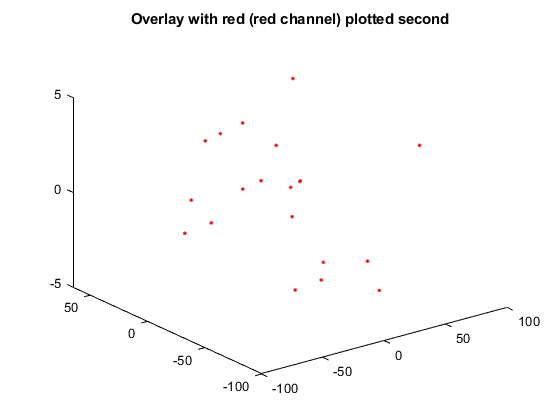

% view([0,90])
figure % Plot points
plot3(orange_bilinear_x, orange_bilinear_y, orange_bilinear_z, '.b')
hold on
plot3(red_xyz_vector(:,1),red_xyz_vector(:,2),red_xyz_vector(:,3),'.r')
hold off
title('Overlay with red (red channel) plotted second')

% view([0,90])

So I started with the Trilinear approach

vector = [x.^2, y.^2, z.^2, x.*z, y.*z, x.*y, x, z, y, x*0+1];

which is a 10 feature transform

Initially there were many 0's as weights to the features created, so removing those features I have been left with a 4 feature transform

x' = a*x + b*y + c*z + d

y' = e*x + f*y + g*z + h

z' = j*x + k*y + l*z + m

This results in the graphs seen to the right, and indicates that by performing this transform the overlay is nearly perfect.

The result is currently being created with a randomly initialized transformation matrix in X Y and Z followed by a randomly initialized rotation about z and the recovery is perfect every time. 